# Power-Split Hybrid Electric Vehicle Model with Direct Input

## MG2 Starts, Drive, and Stop Vehicle

On 10% grade road. Mechanical brake is used to stop the vehicle.

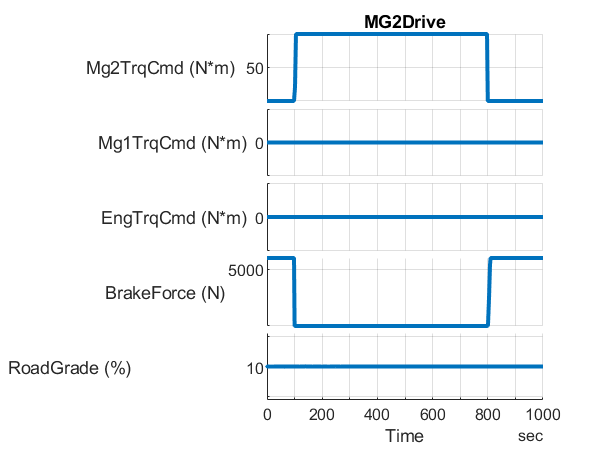

mdl = "PowerSplitHEV_system_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

PowerSplitHEV_params

set_param(mdl+"/Controller & Environment", "ReferencedSubsystem", ...
  "PowerSplitHEV_DirectInput_refsub");

builder = PowerSplitHEV_DirectInput_InputSignalBuilder;
builder.Plot_tf = true;

hevDirectInputData = MG2Drive(builder, ...
  "RoadGrade_Const_pct", 10, ...
  "BrakeForce_1_N", 6000, ...
  "BrakeForce_2_N", 0, ...
  "BrakeForce_3_N", 6000, ...
  "BrakeForceChange_1_StartTime", seconds(99), ...
  "BrakeForceChange_1_EndTime", seconds(100), ...
  "BrakeForceChange_2_StartTime", seconds(800), ...
  "BrakeForceChange_2_EndTime", seconds(810), ...
  "MG2TorqueCommand_1_Nm", 0, ...
  "MG2TorqueCommand_2_Nm", 100, ...
  "MG2TorqueCommand_3_Nm", 0, ...
  "MG2TrqCmdChange_1_StartTime", seconds(100), ...
  "MG2TrqCmdChange_1_EndTime", seconds(105), ...
  "MG2TrqCmdChange_2_StartTime", seconds(798), ...
  "MG2TrqCmdChange_2_EndTime", seconds(800), ...
  "StopTime", seconds(1000) );

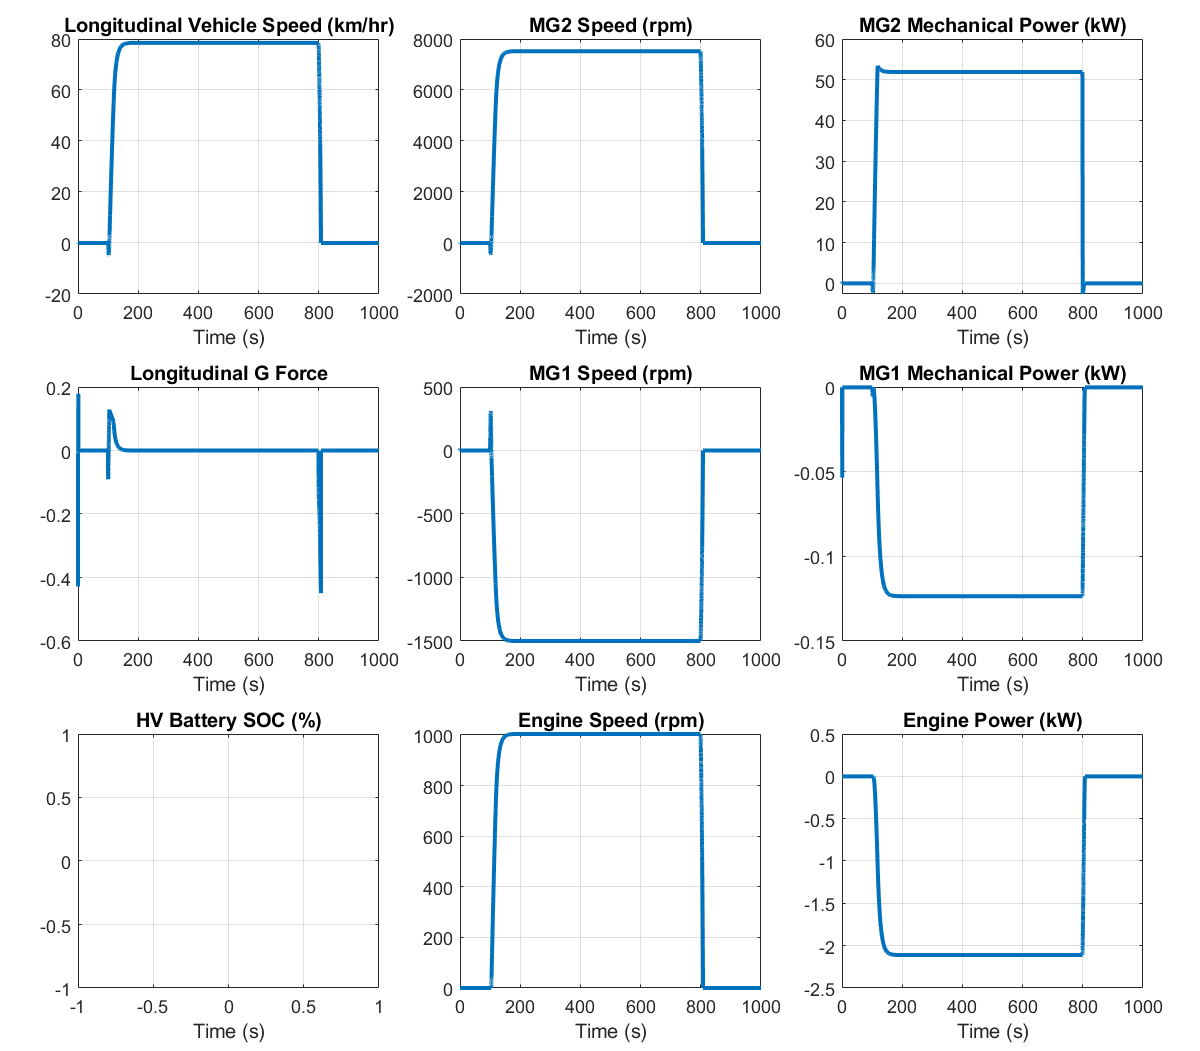


% Load data in the base workspace.
% This allows the Run button to work.
hevDirect_InputSignals = hevDirectInputData.Signals;
hevDirect_InputBus = hevDirectInputData.Bus;
t_end = hevDirectInputData.Options.StopTime_s;

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, "StopTime", num2str(t_end));
simIn = setVariable(simIn, "hevDirect_InputSignals", hevDirect_InputSignals);
simIn = setVariable(simIn, "hevDirect_InputBus", hevDirect_InputBus);

simOut = sim(simIn);

fig = figure;
PowerSplitHEV_plot_result_compact( "Dataset",simOut.logsout, "PlotParent",fig );

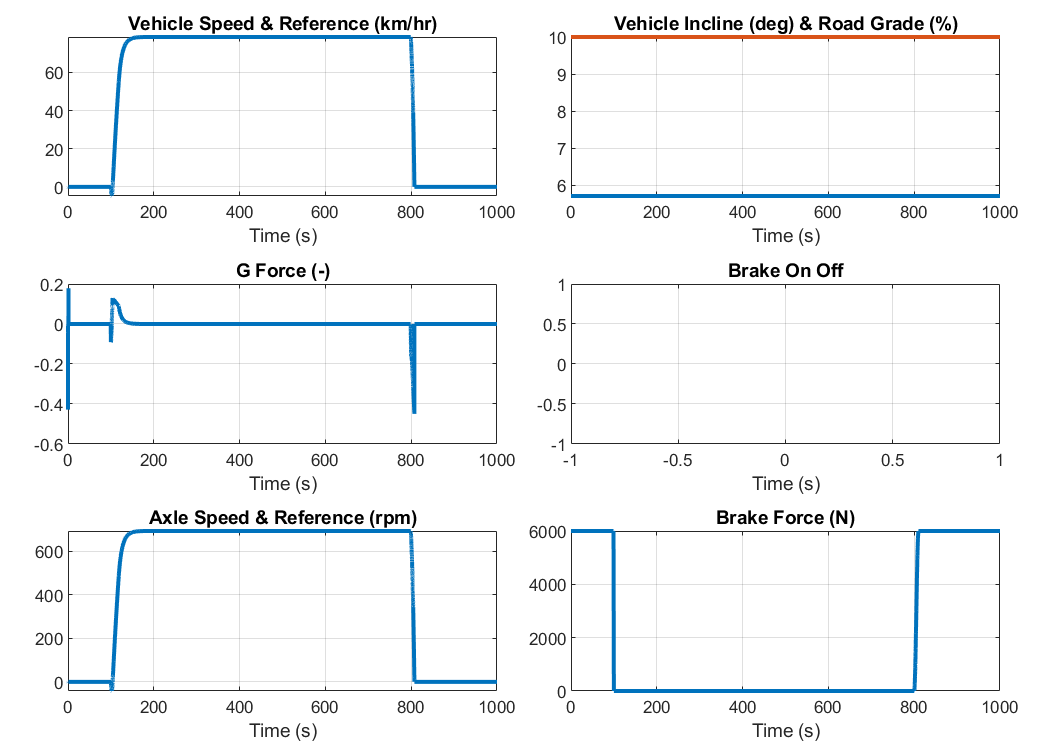

fig = figure;
PowerSplitHEV_plot_result_vehicle( "Dataset",simOut.logsout, "PlotParent",fig );

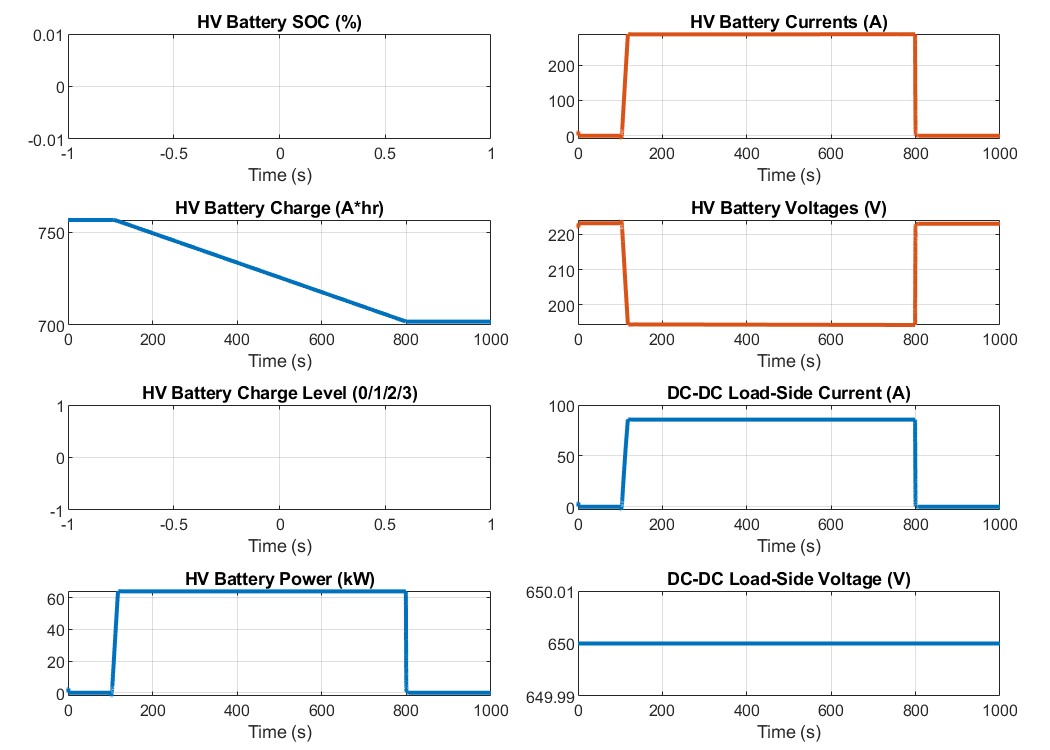

fig = figure;
PowerSplitHEV_plot_result_hvbattery( "Dataset",simOut.logsout, "PlotParent",fig );

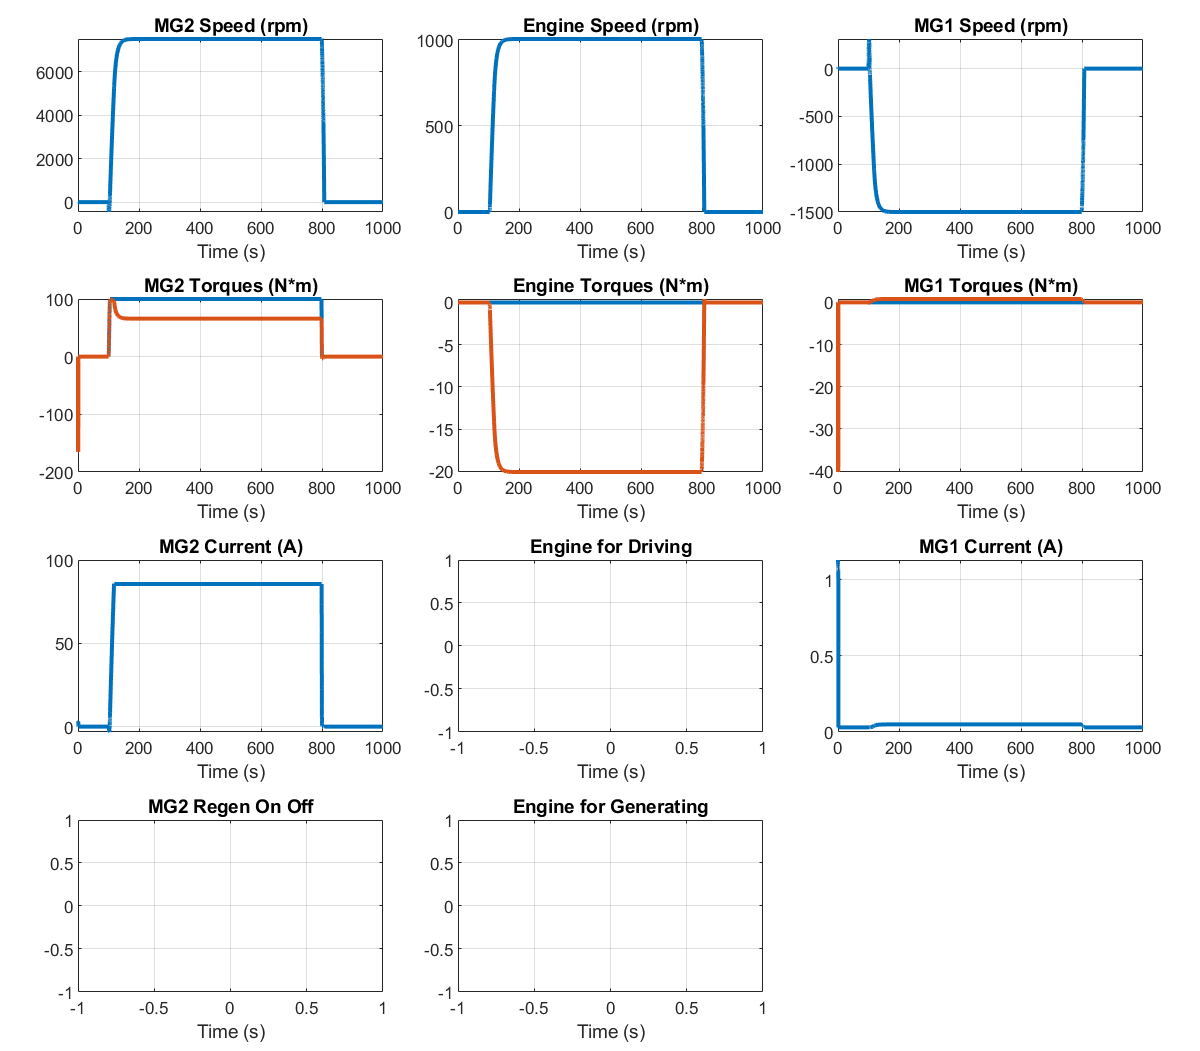

fig = figure;
PowerSplitHEV_plot_result_powersplit( "Dataset",simOut.logsout, "PlotParent",fig );

*Copyright 2021-2022 The MathWorks, Inc.*